clear variables;

fc=28e9; % frequency of operation

%% Substrate properties
hs=0.15748; %mm-- height of substrate
t=18e-3; %thickness of top-layer metal in mm
er=3.66; %permittivity of substrate
Lt=0.004; %loss tangent
Lg=10; %mm-- ground plane width
substrate = dielectric('Name','Rogers4350','EpsilonR',er,'LossTangent',Lt,...
    'Thickness',hs*1e-3);
[Lp,Wp,w0]=patchDim(fc,hs,er,t);
fprintf(1,"Length of the patch: %7.4f mm",Lp);

Length of the patch:  2.7551 mm

fprintf(1,"Width of the patch: %7.4f mm",Wp);

Width of the patch:  3.5096 mm

fprintf(1,"Width of microstrip feed: %7.4f mm",w0);

Width of microstrip feed:  0.3002 mm


%The obtained dimensions are simulated in HFSS. Results obtained are
%slightly modified as:
Lp=2.72;
y0=patchInset(fc,Wp,Lp);
fprintf(1,"Inset on the patch: %7.4f mm",y0);

Inset on the patch:  0.9894 mm

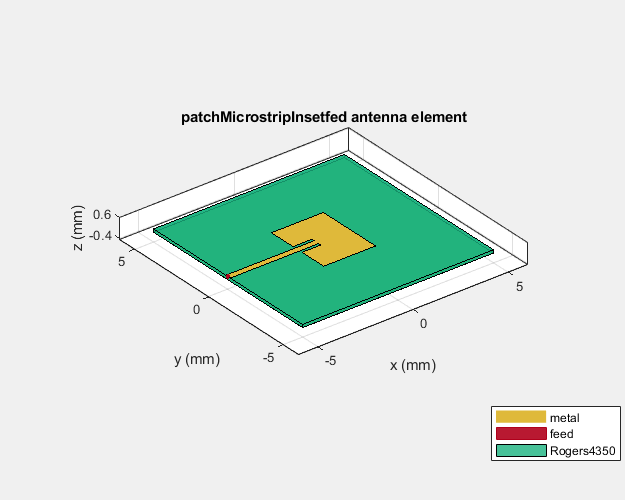


%matlab funstion takes all dimensions in meters. The results are in mm
insetpatch = patchMicrostripInsetfed("Width",Wp*1e-3,"Length",Lp*1e-3,...
    "Height",hs*1e-3,"Substrate",substrate,"NotchLength",y0*1e-3,...
    "NotchWidth",2*w0*1e-3,"StripLineWidth",w0*1e-3,"GroundPlaneLength",Lg*1e-3,...
    "GroundPlaneWidth",Lg*1e-3,"FeedOffset",[-Lg/2*1e-3 0]);

insetpatch.show();

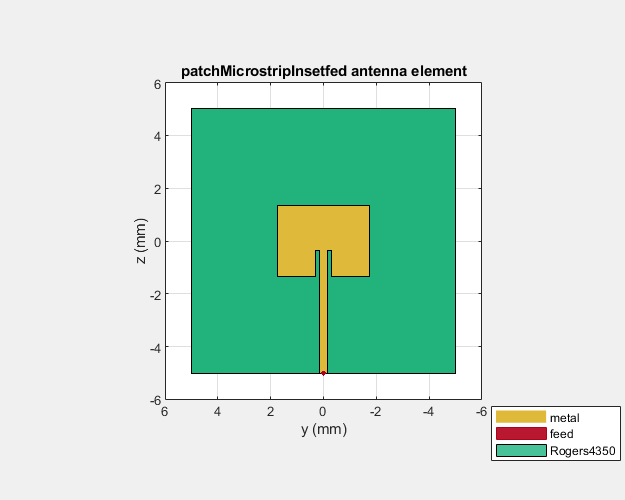


insetpatch.Tilt=-90;
insetpatch.TiltAxis=[0,1,0];
insetpatch.show();
view(-90,0);


eFieldTot=csvread("E_fields28.csv",1,0);
az=eFieldTot(:,1);
theta=eFieldTot(:,2);
Etotal=eFieldTot(:,3).*1e-3;
Etotal=flipud(Etotal); %custom antenna element takes elevation values from -90 to 90 
                        % but fields are stored 90 to -90
el=theta-90;% changing theta to elevation from -90 to 90 to match the flip 
Epow=abs(Etotal).^2;
elrad=deg2rad(el);
scale=mean(cos(elrad))/mean(Epow.*cos(elrad));
dir=scale*Epow;
dir_db=pow2db(dir);

rad_eff=0.51544; %radiation efficiency from HFSS
fprintf(1,"Radiation efficiency evaluated in HFSS: %7.4f",rad_eff);

Radiation efficiency evaluated in HFSS:  0.5154


A_gain=rad_eff.*dir;
gain_db=pow2db(A_gain);

fprintf(1,"Max directivity is: %7.4f dBi",max(dir_db));

Max directivity is:  7.4657 dBi

fprintf(1,"Max gain is: %7.4f dBi",max(gain_db));

Max gain is:  4.5875 dBi


check=mean(dir.*cos(elrad))/mean(cos(elrad));
fprintf(1,"Average value of directivity*cos(elevationAngle) over integration sphere: %7.4f",check);

Average value of directivity*cos(elevationAngle) over integration sphere:  1.0000

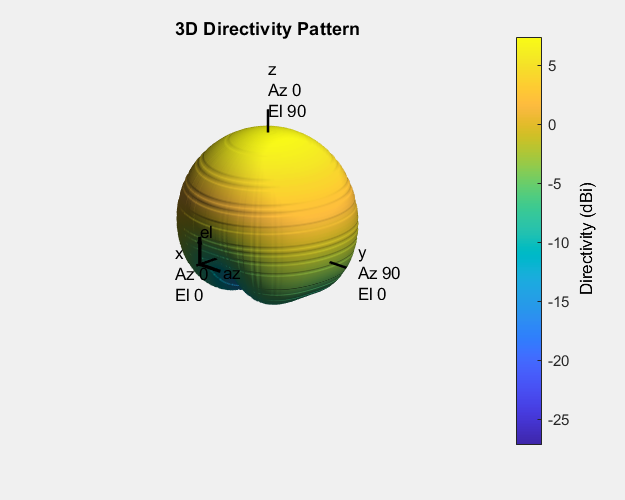


elvals=(-90:2:90)';
azvals=(-180:2:180)';
nel = length(elvals);
naz = length(azvals);

dirMat=reshape(gain_db,naz,nel);
dirMat=dirMat';

im=find(azvals==0);
dirMat=circshift(dirMat,[0,im-1]);

phasePattern=zeros(nel,naz);
ant=phased.CustomAntennaElement('AzimuthAngles',azvals,'ElevationAngles',...
    elvals,'MagnitudePattern',dirMat,'PhasePattern',phasePattern);

ant.pattern(fc);

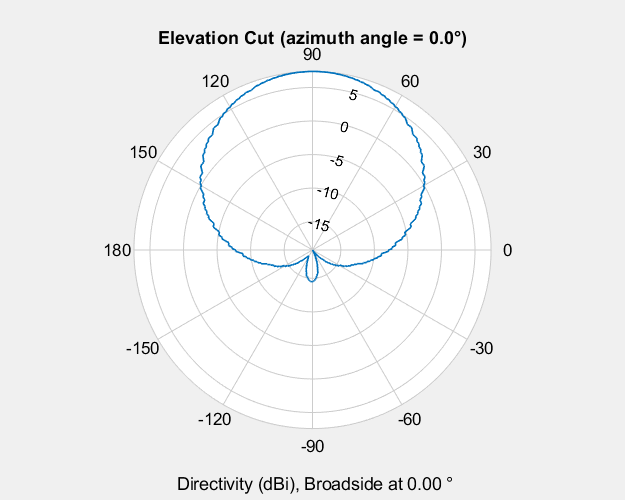

azcut=0;
ant.patternElevation(fc,azcut);

vslice0=ant.patternElevation(fc,azcut);
el_slice=-180:180;
dirmax=max(vslice0);
I=(vslice0>=dirmax-3);
angles=el_slice(I);
angles=sort(angles,'descend');
HPBW=angles(1)-angles(end);
fprintf(1,"Half power beamwidth: %7.4f degrees",HPBW);

Half power beamwidth: 72.0000 degrees

I=(el>=angles(end))&(el<=angles(1));
Ptot=mean(Epow.*cos(elrad));
Phpbw=mean(Epow.*cos(elrad).*I);
fprintf(1,"Power fraction in HPBW: %7.4f",Phpbw/Ptot);

Power fraction in HPBW:  0.4147

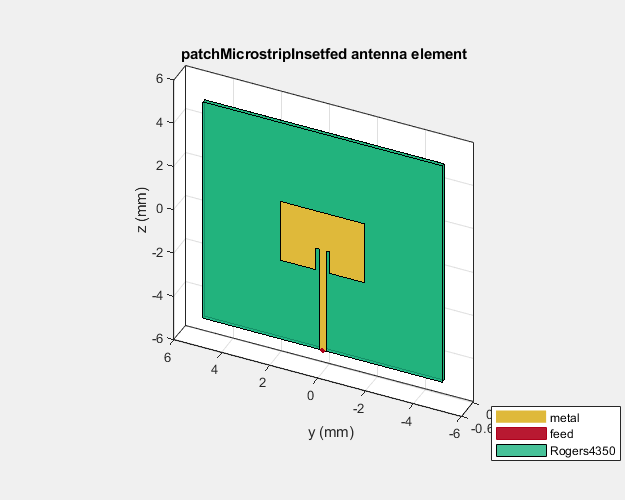


insetpatch.show();
view(-65,35);

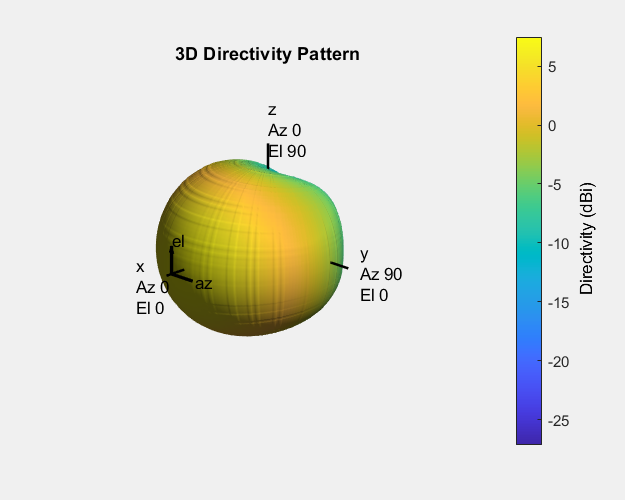

newax = roty(90);
dirMatX=rotpat(dirMat,azvals,elvals,newax);
antX=phased.CustomAntennaElement('AzimuthAngles',azvals,'ElevationAngles',...
    elvals,'MagnitudePattern',dirMatX,'PhasePattern',phasePattern);

antX.pattern(fc);

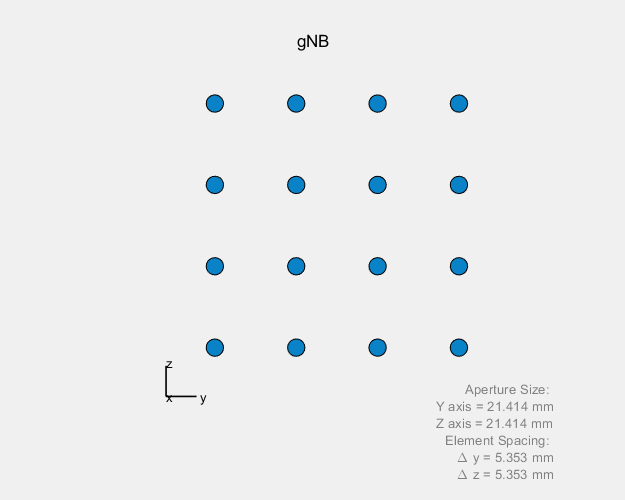

% Number of antennas
nantgNB = [4,4];
nantUE = 8;

lambda = physconst('Lightspeed') / fc;
dsep = 0.5*lambda;
arrgNB = phased.URA(nantgNB,dsep,'Element',antX,'ArrayNormal','x');
viewArray(arrgNB,'Title',"gNB");

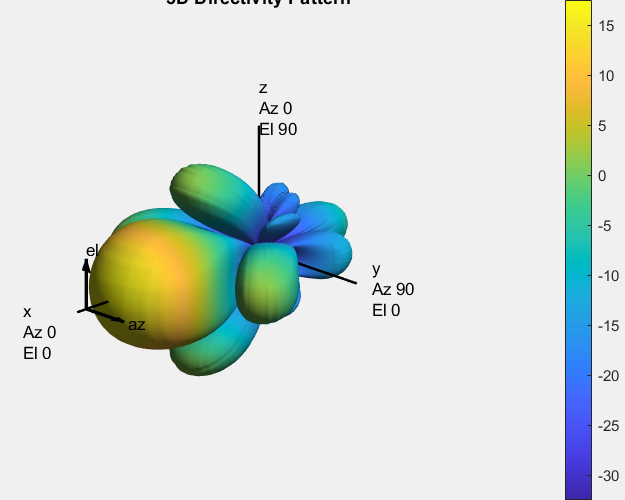

sv = phased.SteeringVector('SensorArray',arrgNB);
ang0 = [0; 0];
sv.release();
u0 = sv(fc, ang0);
u0 = u0 / norm(u0);
arrgNB.pattern(fc,'Weights', u0);

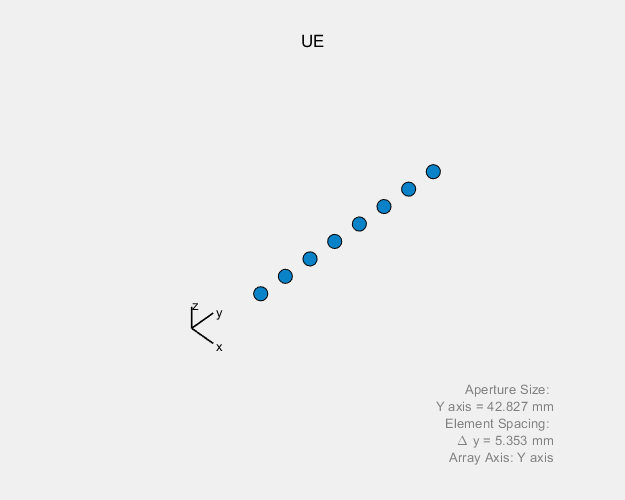

arrUE = phased.ULA(nantUE,dsep,'Element',antX);
viewArray(arrUE,'Title',"UE");

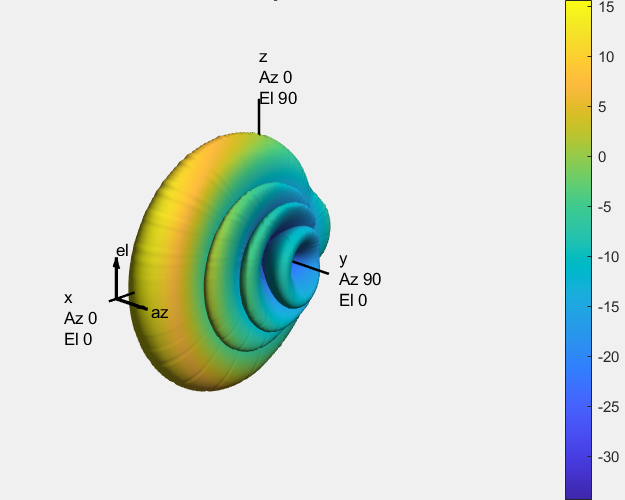

sv = phased.SteeringVector('SensorArray',arrUE);
ang0 = [0; 0];
sv.release();
u0 = sv(fc, ang0);
u0 = u0 / norm(u0);
arrUE.pattern(fc,'Weights', u0);

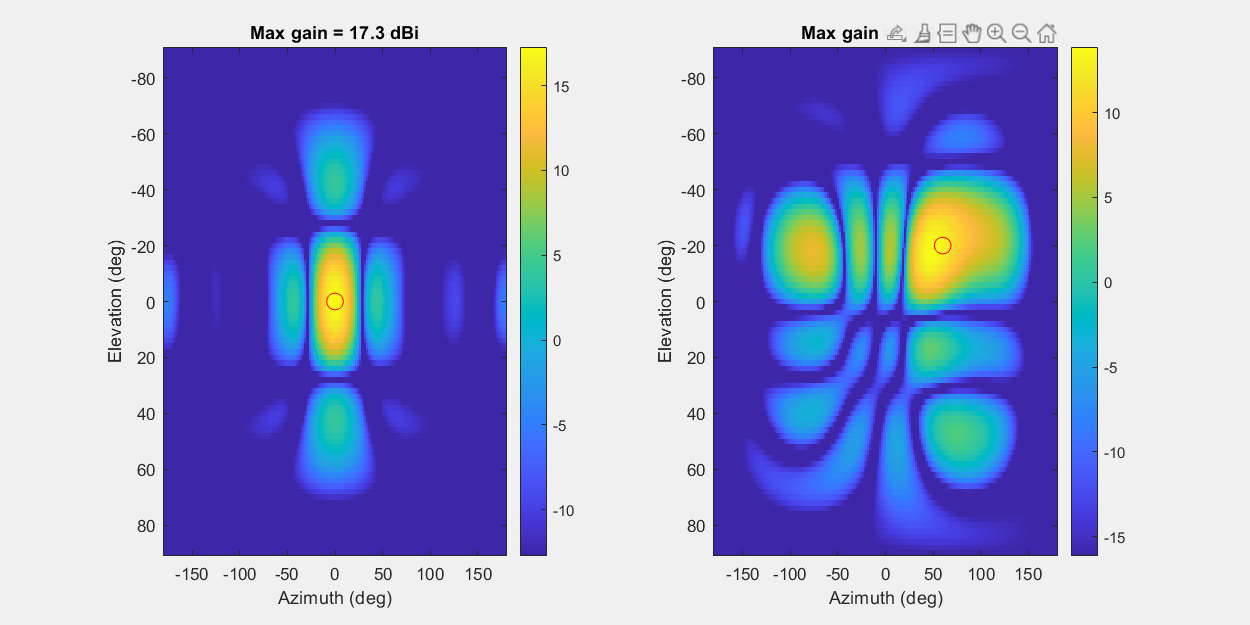

arrPlatformgNB = ArrayPlatform('elem', antX, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();

arrPlatformUE =  ArrayPlatform('elem', antX, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

% Angles to get the beamforming vectors
az0 = [0, 60]';
el0 = [0, -20]';
nw = length(az0);

%the steering vectors
svgNB = arrPlatformgNB.step(az0,el0,true);
svUE = arrPlatformUE.step(az0,el0,true);

% Get grid of values
[azMat, elMat] = meshgrid(azvals, elvals);
azVal = azMat(:);
elVal = elMat(:);

% The BF vectors 
w = conj(svgNB);
wnorm = sqrt(sum(abs(w).^2));
w = w ./ wnorm;
w = w/norm(w);

% Normalized steering vectors at each of the plot angles
Sv = arrPlatformgNB.step(azVal,elVal);

clf;
posOld = get(gcf, 'Position');
set(gcf,'Position', [0,0,1000,500]);

% Looping over the beamforming vectors
for i = 1:nw
    gain = mag2db(abs(w(:,i).'*Sv));%the array gain
    gainMax = max(gain);
    gain = reshape(gain, nel, naz);

    subplot(1,nw,i);
    imagesc(azvals,elvals,gain,[gainMax-30, gainMax]);
    colorbar();
    hold on;
    plot(az0(i),el0(i), 'ro', 'Markersize', 10);
    hold off;
    xlabel('Azimuth (deg)');
    ylabel('Elevation (deg)');
    title(sprintf('Max gain = %3.1f dBi', gainMax));
end

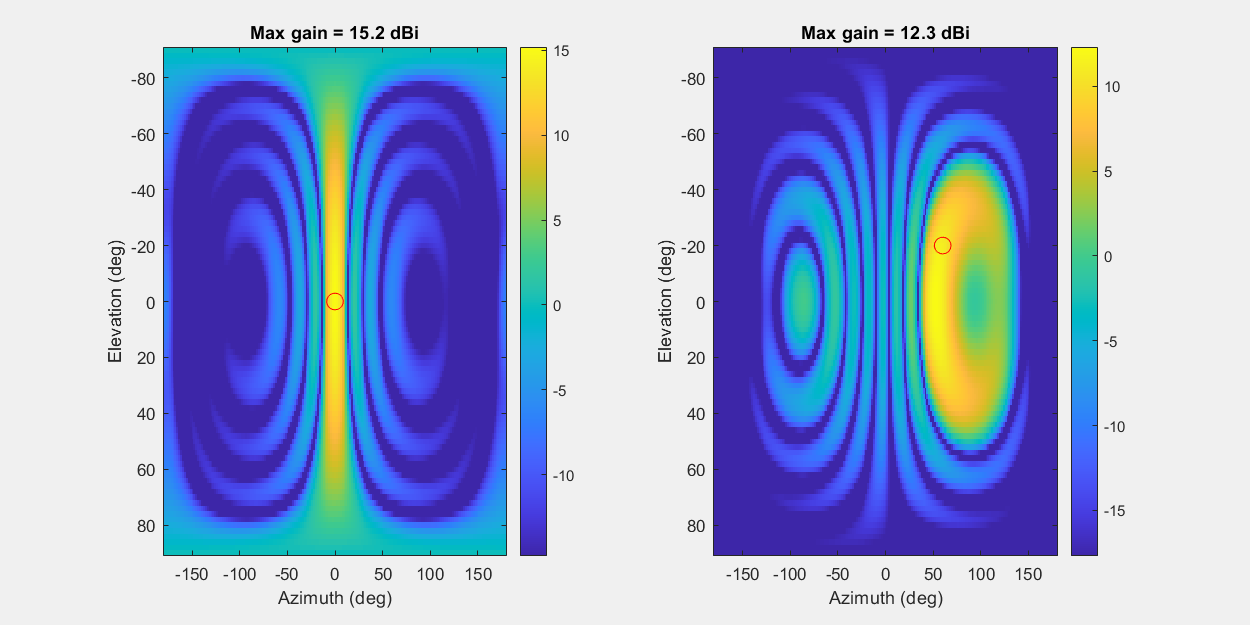

% The BF vectors 
wUE = conj(svUE);
w1norm = sqrt(sum(abs(wUE).^2));
wUE = wUE ./ w1norm;
wUE = wUE/norm(wUE);

% Normalized steering vectors at each of the plot angles
SvUE = arrPlatformUE.step(azVal,elVal);

clf;
posOld = get(gcf, 'Position');
set(gcf,'Position', [0,0,1000,500]);

% Looping over the beamforming vectors
for i = 1:nw
    gainUE = mag2db(abs(wUE(:,i).'*SvUE));%the array gain
    gainMaxUE = max(gainUE);
    gainUE = reshape(gainUE, nel, naz);

    subplot(1,nw,i);
    imagesc(azvals,elvals,gainUE,[gainMaxUE-30, gainMaxUE]);
    colorbar();
    hold on;
    plot(az0(i),el0(i), 'ro', 'Markersize', 10);
    hold off;
    xlabel('Azimuth (deg)');
    ylabel('Elevation (deg)');
    title(sprintf('Max gain = %3.1f dBi', gainMaxUE));
end

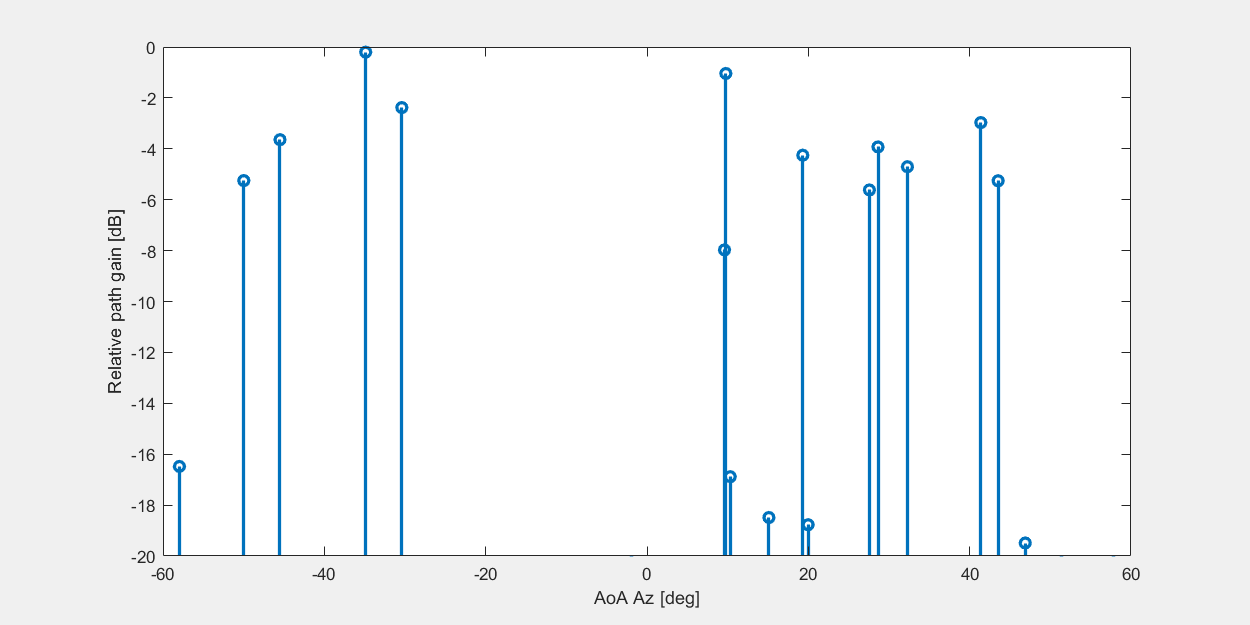

% Path clusters
npaths = 20;
dlysprd = 100e-9;  % delay spread

gain = -exprnd(20,npaths,1); %try higher/lower
[~,maxgainIdx] = max(gain);

dly= unifrnd(-dlysprd,dlysprd,npaths,1);

% Generate random paths
    % Use spatially clustered paths
aodAz = unifrnd(-30,30,npaths,1);
aoaAz = unifrnd(-60,60,npaths,1);  
aoaEl = unifrnd(-10,10,npaths,1);
aodEl = unifrnd(-10,10,npaths,1);

% Plot the paths vs. AoA
clf;
set(gcf,'Position', [0,0,500,400]);
stem(aoaAz, gain, 'Linewidth', 2, 'BaseValue', -20);
ylim([-20,0]);
xlabel('AoA Az [deg]');
ylabel('Relative path gain [dB]');
maxAz=aoaAz(maxgainIdx);
maxEl=aoaEl(maxgainIdx);
arrPlatformUE.alignAxes(maxAz, maxEl);

[svTx, elemGainTx] = arrPlatformgNB.step(aodAz, aodEl);
[svRx, elemGainRx] = arrPlatformUE.step(aoaAz, aoaEl);
gainElem = gain + elemGainTx + elemGainRx;

% Get maximum gain
[~,im] = max(gainElem);

% Find TX BF vector
wtx = conj(svTx(:,im));
wtx = wtx / norm(wtx);

% Find RX BF vector
wrx = conj(svRx(:,im));
wrx = wrx / norm(wrx);

arrGainTx = mag2db(abs(wtx.'*svTx))';
arrGainRx = mag2db(abs(wrx.'*svRx))';
gainArr = gain + arrGainTx + arrGainRx;


set(gcf,'Position', [0,0,1000,500]);

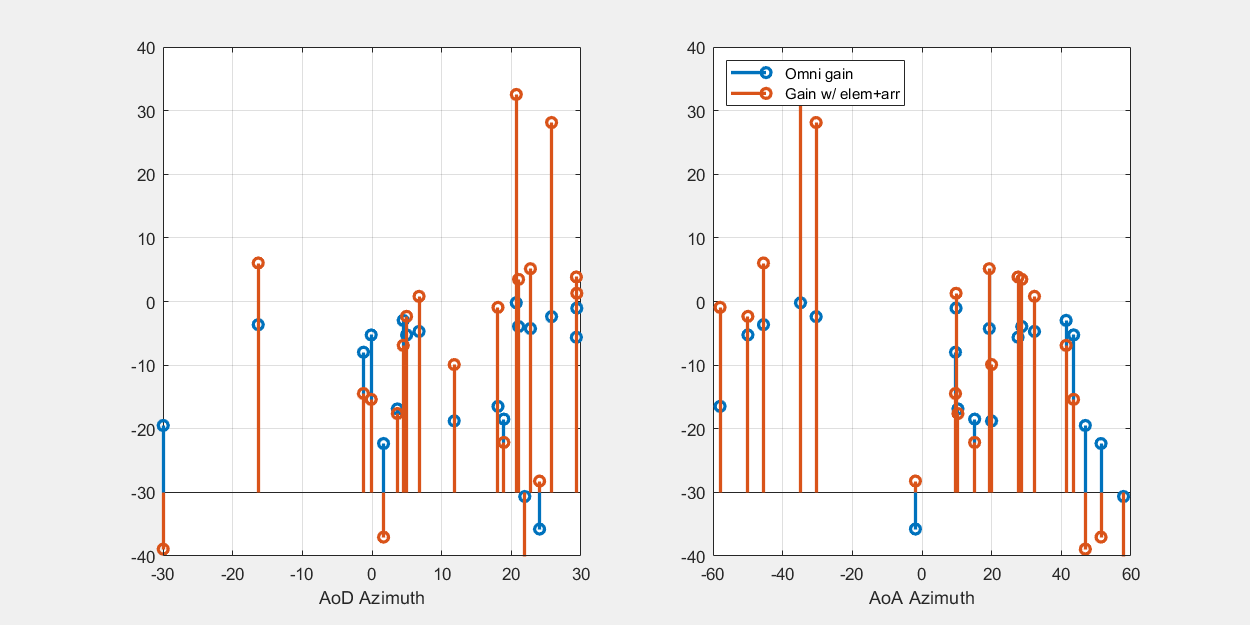

clf;
subplot(1,2,1);
stem(aodAz, [gain gainArr], 'BaseValue',-30, 'LineWidth', 2);
xlabel('AoD Azimuth');
grid on;
ylim([-40,40]);
subplot(1,2,2);
stem(aoaAz, [gain gainArr], 'BaseValue',-30, 'LineWidth', 2);
xlabel('AoA Azimuth');
legend('Omni gain', 'Gain w/ elem+arr', 'Location', 'northwest');
grid on;
ylim([-40,40]);

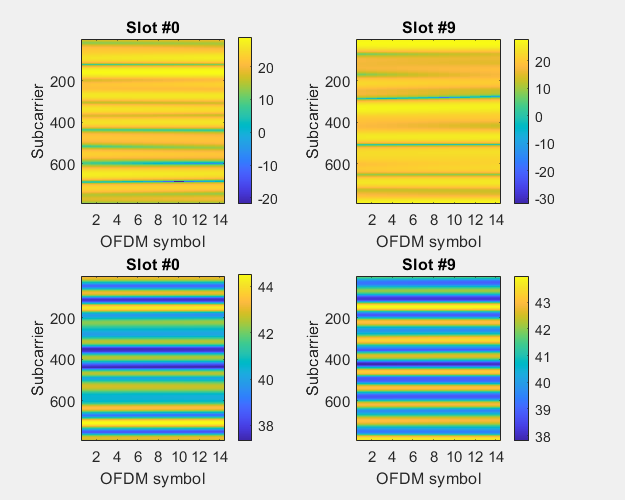


SubcarrierSpacing = 120;  % SCS in kHZ
NRB = 66;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Enoise = -5;  % Energy per noise sample in dB
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);


frameNum = 0;
slotNum = [0,9];
nslot=length(slotNum);
clf;
for i=1:nslot
    [chanGrid, noiseVar] = fdchan.step(frameNum, slotNum(i));
    set(gcf,'Position', [0,0,500,400]);
    chanGainSing = squeeze( abs(chanGrid(3,4,:,:)).^2 );
    snrSing = 10*log10(chanGainSing / noiseVar);
    subplot(2,nslot,i);
    imagesc(snrSing);
    colorbar();
    xlabel('OFDM symbol');
    ylabel('Subcarrier');
    title(sprintf('Slot #%d', slotNum(i))); 
    
    nsc = size(chanGrid,3);
    nsym = size(chanGrid,4);
    snrInst = zeros(nsc,nsym);
    for n = 1:nsc
        for t = 1:nsym
            chani = squeeze(chanGrid(:,:,n,t));
            [wrxi,si,wtxi] = svds(chani, 1);
            
            snrInst(n, t) = pow2db(si^2/noiseVar);
        end
    end
    subplot(2,nslot,nslot+i);
    imagesc(snrInst);
    colorbar();
    xlabel('OFDM symbol');
    ylabel('Subcarrier');
    title(sprintf('Slot #%d', slotNum(i)));
end

Qtx = reshape(SvTx,ntx,1,npaths).*reshape(conj(SvTx),1,ntx,npaths) ...
    .*reshape(abs(gainComplex).^2,1,1,npaths);
Qtx = nrx*sum(Qtx, 3);